# Physiological-based artificial neural network 

We developed artificial neural network inspired by motor cortical and reticulospinal pathways to provide a naturalistic solution for recovering finger dexterity after stroke.

## Model Architicture 

Our clustered ANN model constructed from 3 layers: input, hidden and output. The input layer represents the commands for finger movements generated by motor cortical areas. The hidden layer, the computational heart of the model, represents the cortical primary motor neurons and the brainstem reticular neurons in the medulla/pons. The output layer represents the task action outcome generated by spinal motoneuron pools and muscles.

## 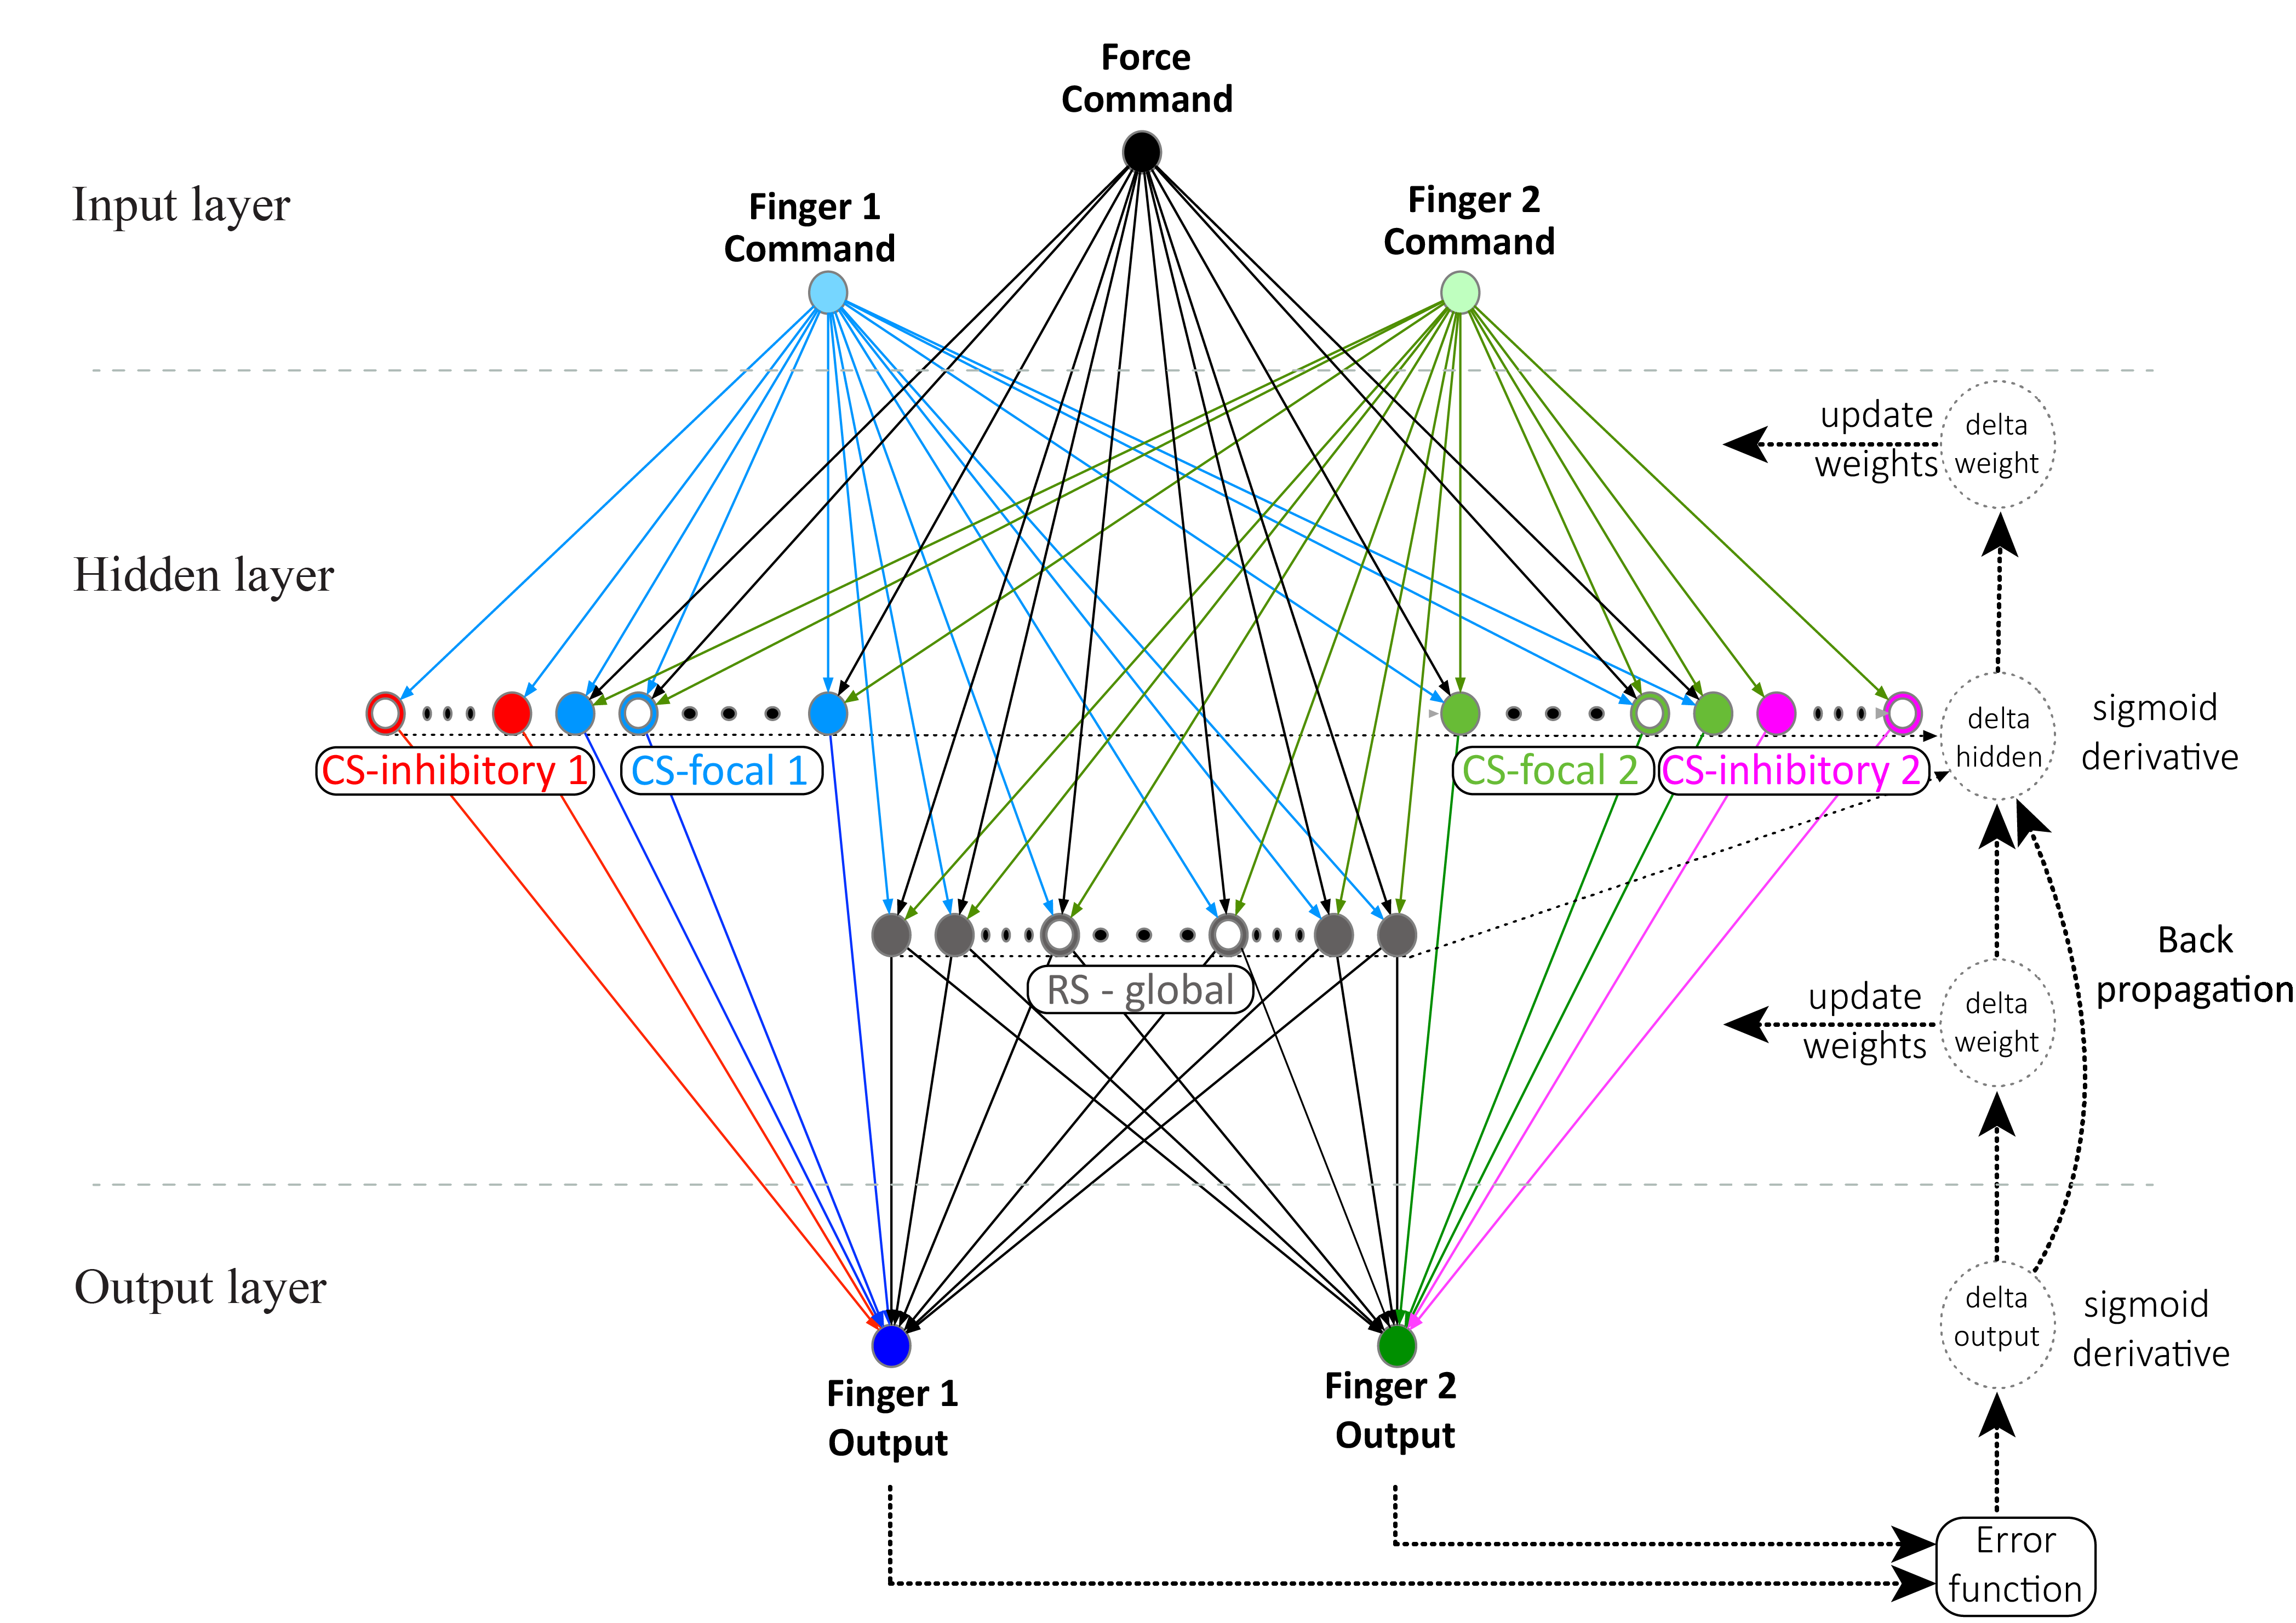

## Model defenition

The ANN model was characterized by three key features:

 1) The number of residual motor cortex neurons in the hidden layers is inversely proportional to the magnitude of the overlap between the lesion and the motor area of the brain. 

 2) The force that each finger muscle generated was determined by the weighted sum activities, up to a saturation limit, of cortical and sub-cortical neurons in the hidden layers. 

3) We assumed that the motor system must find this solution by evaluating the results of task performance based on the deviation of the net force output of the fingers from the desired force targets (i.e., error function as teaching signal).

## Set parameters of the ANN

We set the global parameters to configure the main structure of the NN, e.g., number of hidden layer neurons (N=400), number of inputs (NI=3), and number of outputs (NO=2). We defined the dependent parameters to configure the inner structure of the NN, e.g., focality of the network (focal=0.4, 40%), inhibitory neurons (inhibit=0.05, 5% of the focal), and the rest of the neurons are the RS. We used the training and simulation related parameters to control the learning process, error correction resolution steps (eta=0.01), training cycles as number of days (*nDays*=360), and training repetition in each training cycle as daily dosage ([50, …, 50, 200, …, 200, 50, ..., 50, 0, ..., 0] vector of dosage values per day), defined differently for every stage of the training.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% author: Ashraf Kadry
% purpose: A neural network model of M1 and SMA before and
% after stroke. Here, we explore the roles of individuation and strength 
% resulting from two motoneruonal pools. 
%
% model definition:
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear; close all; clc; set(0,'defaultlinelinewidth',2.5);

%% set parameters
prompt = 'Insert force level [0..1, 1=100% (0 for new random weights, 100% force)]: ';
x = input(prompt);
if(x==0)
    P = setParams();
else
    load('Pinit.mat');
    P.frc = x;
end



Of Note, the initial weigths of the NN were normally distributed:


$$\omega_0 ~Normal\left(\mu =0.5,\mathrm{\ }\mathrm{\ }\sigma^2 =1/12\right)$$


## Set structure of the ANN

For setting up the NN structure we used mask and status variables, based on the functions’ connectivity between the layers and pre/post stroke status 

%% set structure
P = setStruct(P);

Set Structure.


## Train the ANN

For training the ANN, the command targets and instructed force of the two fingers are fed as inputs to the ANN. The fingers’ performance (actual response of the two fingers) were the actual result, i.e., the output of the ANN as calculated in a feed-forward propagation. The error function was calculated and minimized in every iteration of the training process using gradient descent in a back-propagation flow (see Section ‎0, Mathematical Definition). The training for the initial normal condition is achieved by applying a multi-day and recurrent dosage force-based motor tasks to the normal (i.e., healthy) “pre-stroke” ANN, starting from an initially randomized state and converging to the desired instructed finger commands behavior. 

%% Train Model

% healthy training dosage init
P.dosage = ones(1,P.nDays);
% First 100 days, dosage=200 for every day
P.dosage(1:100) = P.dosage(1:100)*200;
% Next 100 days, dosage=500 for every day  
P.dosage(101:200) = P.dosage(101:200)*500;  
% Next 100 days, dosage=50 for every day
P.dosage(201:300) = P.dosage(201:300)*50;  
% Last 60 days, dosage=10 for every day
P.dosage(301:P.nDays) = P.dosage(301:P.nDays)*10;

% train model;
[ExpOut,Hidden,Finger1,Finger2,Error1,Error2,Individuation,WH,WO,BH,BO] = trainModel(P);

Training ........................................................................................................................................................................................................................................................................................................................................................................ Completed.


% update trained weights
P.wh = WH;  % weights from Inputs to Hidden layer
P.wo = WO;  % weights from Hidden layer to Outputs
P.bh = BH;  % bias weights to Hidden layer
P.bo = BO;  % bias weights to Output layer

## Simulate the stroke 

We simulated a stroke by disabling a portion of the neurons in the hidden layer of the trained ANN, in proportion to the severity of the stroke. To emphasize this, the lesion state was the actual outcome of the injured trained model without further training. The force-based motor commands were simulated at the stroke condition and the fingers’ outcome values were collected. 

Immediately after the lesion, the recovery process of the residual ANN represented the recovery that typically occurs at the early post-stroke phase and may continue to the chronic phase. The ANN is trained following the same method applied during the initial stage, and the simulation data is collected as well, but with the stroke condition as a starting point. 

%% Apply stroke
P.stroke = 0.40;                % 40% stroke
[Hstatus,Eta]  = setStroke(P);  % Apply stroke on hidden layer
P.Nstatus = Hstatus;            % Update hidden Neurons status
P.eta = Eta;                    % new learning ratio after stroke

%% Simulate stroke
[sHidden,sFinger1,sFinger2,sError1,sError2,sIndividuation] = simulateModel(P);

Simulating ... Completed.



%% Train Model after stroke

% after stroke training dosage init
P.dosage = ones(1,P.nDays);  
% First 10 days, dosage=1 for every day
P.dosage(1:10) = P.dosage(1:10);
% Next 40 days, dosage=5 for every day  
P.dosage(11:50) = P.dosage(11:50)*5;  
% Next 100 days, dosage=25 for every day  
P.dosage(51:150) = P.dosage(51:150)*25;  
% Next 30 days, dosage=1 for every day  
P.dosage(151:180) = P.dosage(151:180)*1;
% Last 180 days, dosage=0 for every day
P.dosage(181:P.nDays) = P.dosage(181:P.nDays)*0;  

% train model
[tsExpOut,tsHidden,tsFinger1,tsFinger2,tsError1,tsError2,tsIndividuation,tsWH,tsWO,tsBH,tsBO] = trainModel(P);

Training after stroke........................................................................................................................................................................................................................................................................................................................................................................ Completed.


% update trained weights
P.wh = tsWH;  % weights from Inputs to Hidden layer
P.wo = tsWO;  % weights from Hidden layer to Outputs
P.bh = tsBH;  % bias weights to Hidden layer
P.bo = tsBO;  % bias weights to Output layer

%% save results for later use and begin plotting
save('modelData');

## Plot the results

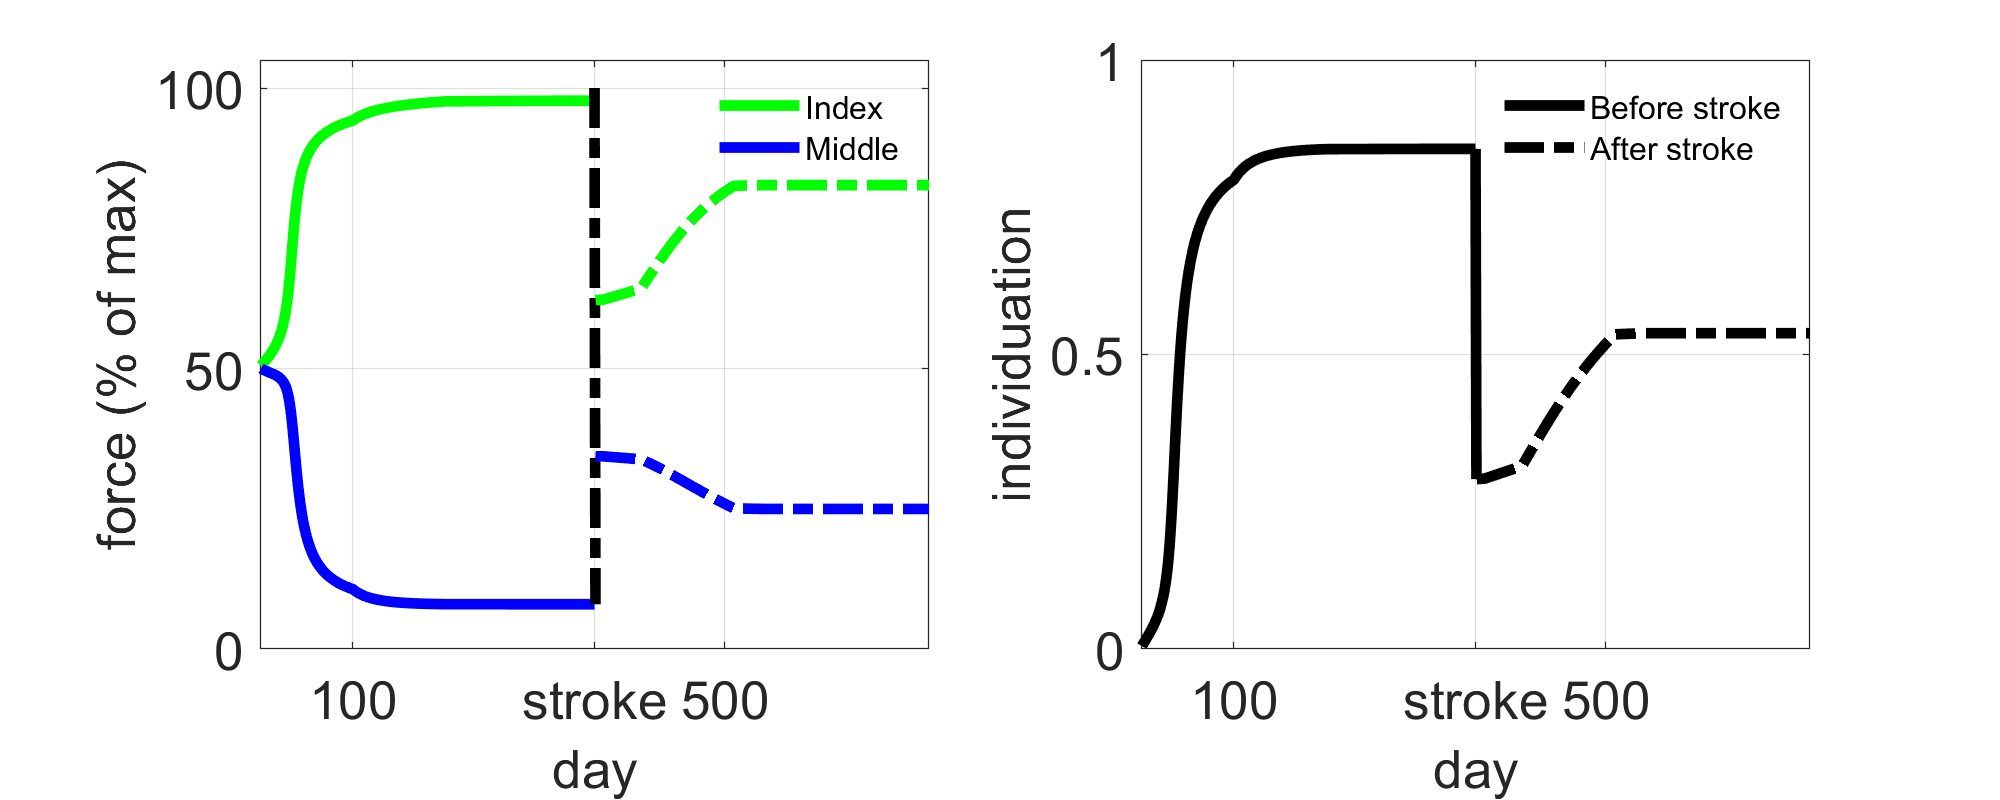

%% plot graphs
plotResults(1,1); % Index finger, force level=100%

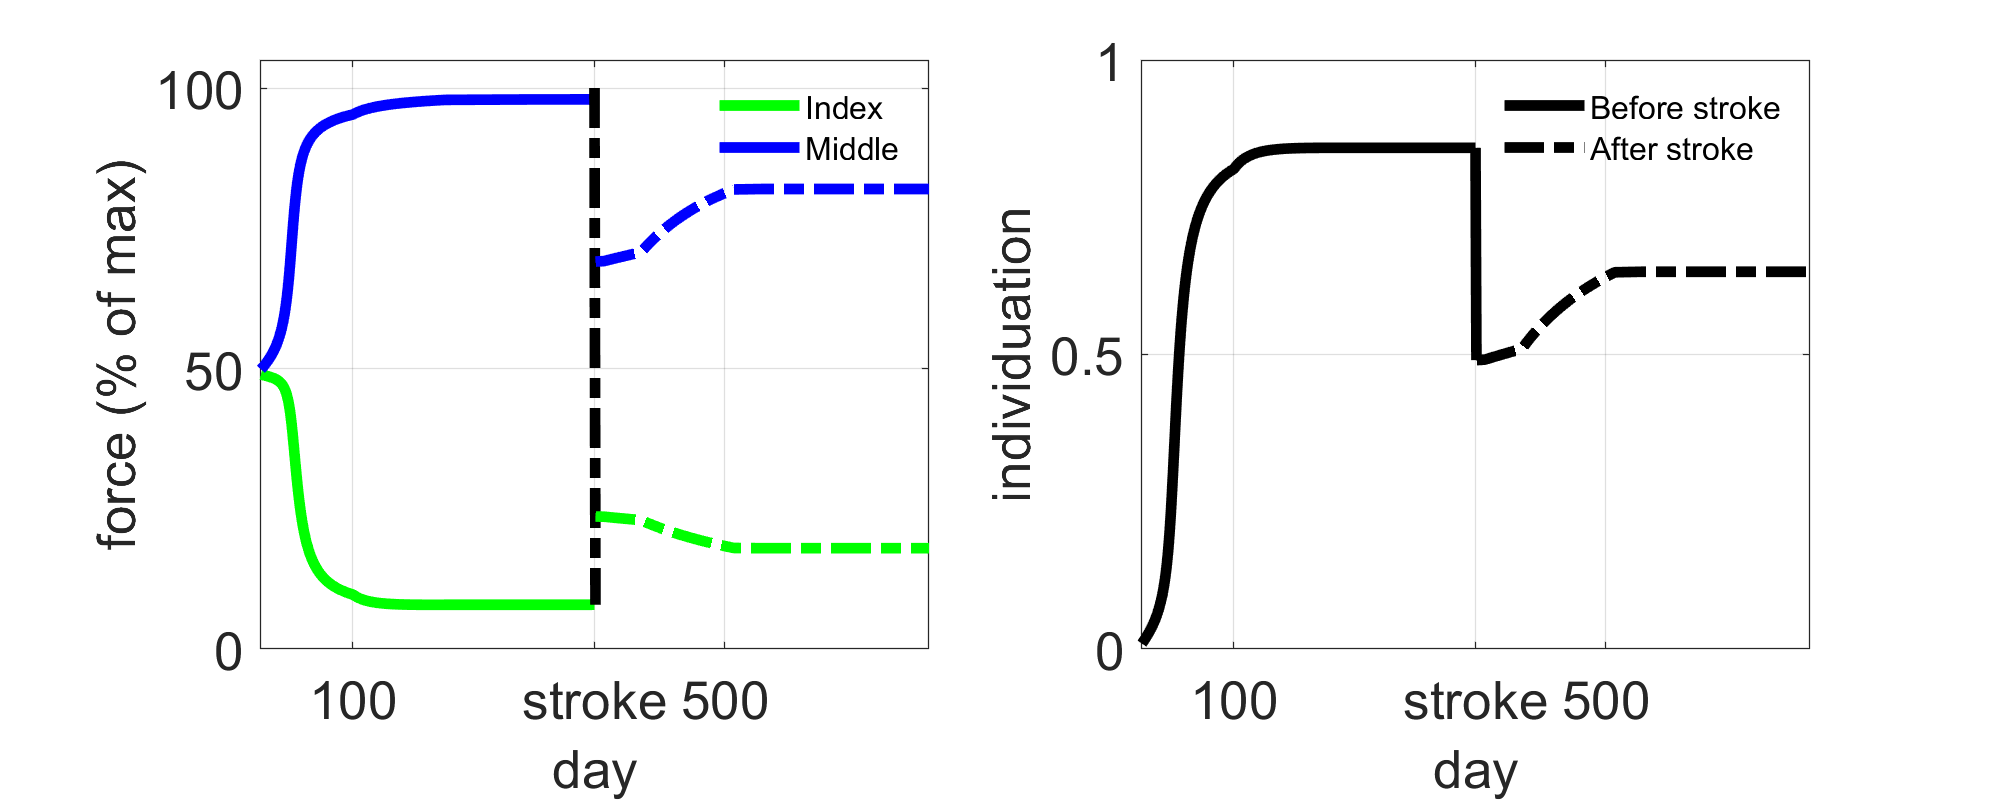

plotResults(1,2); % Middle finger, force level=100%

## Useful functions:

The function setParams() initilizes the model parameters as follows:

function P = setParams()
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% inputs:
% 
% outputs: 
% P - a parameter structure for the model (see MAIN).
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% Global Parameters
    fprintf('Set Parameters.\n');
    P.NumFingers = 2;   % number of Inputs/Outputs (# fingures)
    P.NumIn = P.NumFingers + 1;    % number of Inputs (force, encoded fingures)
    P.NumOut = P.NumFingers;       % number of Outputs (# fingures)
    P.N = 400;          % number of neurons in hidden layer
    P.fRate = 1.00;     % firing rate
    P.nDays = 360;      % number of days to run the simulation
    P.alpha = 0.5;      % ratio for value function | 0 indiv | 1 force
    P.wNoise = 0.1;     % noise weight
    P.amode = [0 0];    % activation type (0 Sigmoid | 1 ReLU/LeakyReLU)
    P.mode = 3;         % feedback type (0 force OR indiv | 1 force  | 2 individuation | 3 value function)
    P.Nstatus = ones(1,P.N);         % Hidden neurons status (1 active/normal | -1 active/inhibitory | 0 inactive/stroke)
    P.iWmask = ones(P.NumIn,P.N);    % inhibitory neurons mask (1 connected | 0 not-connected)
    P.Wmask = ones(P.N,P.NumOut);    % focal and RS neurons mask (1 connected | 0 not-connected)

%% Dependent Parameters
    P.eta = 0.01;         % initial learning ratio
    P.dosage = ones(1,P.nDays);  % initial training dosage
    P.stroke = 0;     % level of stroke (0 to 1) 
    P.focal = 0.4;    % percentage of focality of the network (ratio representation)
    P.inhibit = 0.05; % percentage of inhibtory neurons of focal CS (ratio representation)
    P.cmd = [1.0 -1.0; -1.0 1.0];
    P.frc = 1;
    sCmd = (P.cmd+1.0)/2.0;
    sFrc = (1.-sCmd);
    
    % Set inslaving on passive finger
    P.inslave_c = sCmd;
    P.inslave_f = sFrc;
    P.inslave_a = 0.06;
    P.inslave_b = 0.02;

%% Initial Weights
    fprintf('Initialize Weights.\n');
    P.wh = rand(P.NumIn,P.N); % weights from Inputs to Hidden layer
    P.wo = rand(P.N,P.NumOut); % weights from Hidden layer to Outputs
    P.bh = -6*ones(1,P.N)+randn(1,P.N);  % bias weights to Hidden layer
    P.bo = -ones(1,P.NumOut); % bias weights to Output layer
    
%% Set type of neurons: focal or inhibitory
    % Setting up unimpaired network
    % Number of focal (include inhibitory) neurons per IO finger
    nFocal = floor(P.focal*P.N/P.NumOut);
    P.nFocal = nFocal;
    % Inhibitory neurons (percentage of focal neurons) per IO finger
    nInhibit = ceil(nFocal*P.inhibit);
    P.nInhibit = nInhibit;
    % Number of total RS neurons
    nRS = P.N-2*nFocal;
    P.nRS = nRS;

%% Save initial parameters
    save('Pinit.mat','P');
end

The function setStructure() sets up the structure of the model as follows:

function P = setStruct(P)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% inputs:
% 
% outputs: 
% P - a parameter structure for the model (see MAIN).
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% NN Structure
    fprintf('Set Structure.\n');
    
%% Set type of neurons: focal or inhibitory
    % Number of focal (include inhibitory) neurons per IO finger
    nFocal = P.nFocal;
    % focal neurons
    focalIndsF1 = 1:nFocal;
    focalIndsF2 = P.N-nFocal+1:P.N;
    % Focal neurons connectivity to fingers (Hidden to Out)
    P.wo(focalIndsF2,1) = 0; % finger1 CS focal neurons does not connect to finger2
    P.wo(focalIndsF1,2) = 0; % finger2 CS focal neurons does not connect to finger1
    % use mask to prevent updating cleared focal weights on backpropagation learning
    P.Wmask(focalIndsF2,1) = 0;
    P.Wmask(focalIndsF1,2) = 0;

    % Focal neurons connectivity to fingers (input to Hidden)
    % excitatory neurons
    P.wh(3,focalIndsF1) = 0; % Force input does not affect First finger focal
    P.wh(3,focalIndsF2) = 0; % Force input does not affect Second finger focal
    % use mask to prevent updating cleared focal weights on backpropagation learning
    P.iWmask(3,focalIndsF1) = 0;
    P.iWmask(3,focalIndsF2) = 0;
    
    % inhibitory neurons (percentage of focal neurons) per IO finger
    nInhibit = P.nInhibit;
    inhIndsF1 = focalIndsF1(1:nInhibit);
    inhIndsF2 = focalIndsF2(nFocal-nInhibit+1:nFocal);
    % Separate inhibitory neurons for each IO Finger, not connected to force IO 
    P.wh(2,inhIndsF1) = 0; % Second finger does not affect First finger inhibitory
    P.wh(1,inhIndsF2) = 0; % First finger does not affect Second finger inhibitory
    P.wh(3,inhIndsF1) = 0; % Force input does not affect First finger inhibitory
    P.wh(3,inhIndsF2) = 0; % Force input does not affect Second finger inhibitory
    % use mask to prevent updating cleared inhibitory weights on backpropagation learning
    P.iWmask(2,inhIndsF1) = 0;
    P.iWmask(1,inhIndsF2) = 0;
    P.iWmask(3,inhIndsF1) = 0;
    P.iWmask(3,inhIndsF2) = 0;

    % Inhibitory neurons are negative
    P.Nstatus(1,inhIndsF1) = -1.;
    P.Nstatus(1,inhIndsF2) = -1.;

end

The function trainModel() trains the ANN as follows:

function [ExpOut,H,F1,F2,E1,E2,Indiv,WH,WO,BH,BO] = trainModel(P)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% author: Ashraf Kadry
% function: trainModel(P)
% 
% inputs:
% P - a parameter structure for the model (see MAIN).
% 
% outputs:
% F1 - finger 1 force matrix (day x command)
% F2 - finger 2 force matrix (day x command)
% E1 - finger 1 error matrix (day x command)
% E2 - finger 2 error matrix (day x command)
% Indiv - Individuation matrix (day x command), (when same, value = -1)
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

if (P.stroke == 0)
    fprintf('Training ');
else
    fprintf('Training after stroke');
end

%% Initialization
Cmd   = P.cmd;
Force = P.frc;
sBo = Force.*P.bo;
sBh = Force.*P.bh;

NumFngrOut = P.NumFingers;

% Calc inslaving for passive finger
sCmd     = P.inslave_c;
sFrc     = P.inslave_f;
aInslave = P.inslave_a;
bInslave = P.inslave_b;
xInslave = Force.*sFrc;
yInslave = aInslave.*xInslave+bInslave;

% Calc expected output
ExpOut = zeros(length(Cmd),NumFngrOut,1);
ExpOut(:,:,1) = Force.*sCmd + yInslave.*sFrc;

% Testing sample value per day
H = zeros(P.nDays,P.N);
F1 = zeros(length(Force),P.nDays,length(Cmd));
F2 = zeros(length(Force),P.nDays,length(Cmd));
E1 = zeros(length(Force),P.nDays,length(Cmd));
E2 = zeros(length(Force),P.nDays,length(Cmd));
Indiv = zeros(length(Force),P.nDays,length(Cmd));

%% Train
iFrc = Force;
for day = 1:P.nDays
  fprintf('.');
  % a number of trials for the given day
  if P.dosage(day)==0
    for index = 1:length(Cmd)   
            if day==1
                % day 1
                iCmd = Cmd(index,:);
                iExp = ExpOut(index,:,1);
                % Initial Finger values
                [F,H] = getFinger(iFrc,iCmd,P.wh,P.wo,sBh,sBo,P.fRate,P.amode,P.Nstatus);
                F1(1,1,index) = F(1);
                F2(1,1,index) = F(2);
                % Initial Error
                E = getError(iExp,F);
                E1(1,1,index) = E(1);
                E2(1,1,index) = E(2);
                Indiv(1,1,index) = getIndividuation(iExp,F);
            else
                F1(1,day,index) = F1(1,day-1,index);
                F2(1,day,index) = F2(1,day-1,index);    
                E1(1,day,index) = E1(1,day-1,index);
                E2(1,day,index) = E2(1,day-1,index);
                Indiv(1,day,index) = Indiv(1,day-1,index);
            end
    end
  else % day > 1
    for trial = 1:P.dosage(day)
        for index = 1:length(Cmd)   
                % Select Finger Command
                iCmd = Cmd(index,:);
                iExp = ExpOut(index,:,1);
                % Forward Pass
                [fingerO,hidO] = forwardPropagation(iFrc,iCmd,P.wh,P.wo,sBh,sBo,P.fRate,P.amode,P.Nstatus);
                % Backward Pass
                [dWh,dWo,~,~] = backPropagation(iExp,iFrc,iCmd,P.wo,hidO,fingerO,P.amode);
                % Update Output Layer Weights
                newWo = updateWeights(P.eta,(P.wo).',dWo);
                P.wo = dot(newWo.',P.Wmask,P.N);
                % keep initial bias to force positive values on the output weights
                % Update Hidden Layer Weights
                newWh = updateWeights(P.eta,P.wh,dWh);
                P.wh = dot(newWh,P.iWmask,P.N);
                % keep initial bias to force positive values on the hidden weights
        end
    end
    % testing sample value per day  
        for index = 1:length(Cmd)   
            % Select Finger Command
            iCmd = Cmd(index,:);
            iExp = ExpOut(index,:,1);
            % Register training progress
            [F,H] = getFinger(iFrc,iCmd,P.wh,P.wo,sBh,sBo,P.fRate,P.amode,P.Nstatus);
            F1(1,day,index) = F(1);
            F2(1,day,index) = F(2);
            % Error progress
            E = getError(iExp,F);
            E1(1,day,index) = E(1);
            E2(1,day,index) = E(2);
            % Individuation progress
            Indiv(1,day,index) = getIndividuation(iExp,F);
        end
  end
end
fprintf(' Completed.\n');

WH = P.wh;  % weights from Inputs to Hidden layer
WO = P.wo;  % weights from Hidden layer to Outputs
BH = P.bh;  % bias weights to Hidden layer
BO = P.bo;  % bias weights to Output layer

%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [o_out,h_out] = forwardPropagation(frc,cmd,wh,wo,bh,bo,frat,amode,hstat)
    if (amode(1) == 0)
        h_out = calcHiddenOutSig(frc,cmd,wh,bh,frat,hstat);
    else
        h_out = calcHiddenOutRelu(frc,cmd,wh,bh,frat,hstat);
    end

    if (amode(2) == 0)
        o_out = calcOutputOutSig(h_out,wo,bo,frat);
    else
        o_out = calcOutputOutRelu(h_out,wo,bo,frat);
    end
end

function h = calcHiddenOutSig(frc,cmd,wh,bh,frat,hstat)
    h_in = [cmd frc]*wh;
    h_sum = h_in + bh;
    activation = 1./(1.+exp(-h_sum));
    h = dot(hstat,(frat*activation),1);
end

function h = calcHiddenOutRelu(frc,cmd,wh,bh,frat,hstat)
    h_in = [cmd frc]*wh;
    h_sum = h_in + bh;
    % ReLU
    activation = h_sum;
    for h_index = 1:length(h_sum)
        if (h_sum(h_index) < 0)
            % LeakyReLU
            activation(h_index) = 0.01*h_sum(h_index);
        end
    end
    h = dot(hstat,(frat*activation),1);
end

function o = calcOutputOutSig(h,wo,bo,frat)
    o_sum = h*wo + bo;
    % Sigmoid
    activation = 1./(1.+exp(-o_sum));
    o = frat*activation;
end

function o = calcOutputOutRelu(h,wo,bo,frat)
    o_sum = h*wo + bo;
    o_sum = min(frat,o_sum);   %set saturation limits on o_sum       
    % ReLU
    activation = o_sum;
    for o_index = 1:length(o_sum)
        if (o_sum(o_index) < 0)
            % LeakyReLU
            activation(o_index) = 0.01*o_sum(o_index);
        end
    end
    o = activation;
end

function [dwh,dwo,dbo,dbh] = backPropagation(expo,frc,cmd,wo,ho,oo,amode)
    if (amode(2) == 0)
        deltaO = calcDeltaOutSig(expo,oo);
    else
        deltaO = calcDeltaOutRelu(expo,oo);
    end
    dwo    = deltaO.'*ho;
    dbo    = deltaO;
    if (amode(1) == 0)
        deltaH = calcDeltaHiddenSig(deltaO,wo,ho);
    else
        deltaH = calcDeltaHiddenRelu(deltaO,wo,ho);
    end
    dwh    = [cmd frc].'*deltaH;
    dbh    = deltaH;
end

function do = calcDeltaOutSig(expo,oo)
    % error = -(cmd_i-Out_i);
    % derivative = Out_i*(1-Out_i);
    % deltaO_i = error*derivative
    %do = -dot(dot((cmd - oo),oo,1),(1.-oo),1);
    err = -(expo-oo);
    % Sigmoid
    div = dot(oo,(1.-oo),1);
    do  = dot(err,div,1);
end

function do = calcDeltaOutRelu(expo,oo)
    % error = -(cmd_i-Out_i);
    % deltaO_i = error*derivative
    err = -(expo-oo);
    % ReLU
    div = ones(1,length(err));
    for e_index = 1:length(err)
        if (err(e_index) < 0)
            % LeakyReLU
            div(e_index) = 0.01;
        end
    end
    do  = dot(err,div,1);
end

function dh = calcDeltaHiddenSig(do,wo,ho)
    % derivative = Hid_i*(1-Hid_i);
    % deltaO_i_wO_k = Sum_i(deltaO_i*wO_k)
    %dh = dot(dot(dowo,ho,1),(1.-ho),1);
    div = dot(ho,(1.-ho),1);
    dowoSum = do*wo.';
    dh = dot(dowoSum,div,1);
end

function dh = calcDeltaHiddenRelu(do,wo,ho)
    % deltaO_i_wO_k = Sum_i(deltaO_i*wO_k)
    % ReLU
    div = ones(1,length(ho));
    for e_index = 1:length(ho)
        if (ho(e_index) < 0)
            % LeakyReLU
            div(e_index) = 0.01;
        end
    end
    dowoSum = do*wo.';
    dh = dot(dowoSum,div,1);
end

function w = updateWeights(eta,w,dw)
        w = w-eta.*dw;
end

function [f,h] = getFinger(frc,cmd,wh,wo,bh,bo,frat,amode,hstat)
    if (amode(1) == 0)
        h_out = calcHiddenOutSig(frc,cmd,wh,bh,frat,hstat);
    else
        h_out = calcHiddenOutRelu(frc,cmd,wh,bh,frat,hstat);
    end
    if (amode(2) == 0)
        o_out = calcOutputOutSig(h_out,wo,bo,frat);
    else
        o_out = calcOutputOutRelu(h_out,wo,bo,frat);
    end
    h = h_out;
    f = o_out;
    f = max(0.02,f);   %set saturation limits on f
end

function mse = getError(c,f)
    e1 = c(1)-f(1);
    e2 = c(2)-f(2);
    mse1 = 0.5*(e1^2);
    mse2 = 0.5*(e2^2);
    mse =  [mse1 mse2];
end

function indiv = getIndividuation(c,f)
    c1 = c(1);
    c2 = c(2);
    f1 = f(1);
    f2 = f(2);
    indiv = abs(f1-f2)/(f1+f2);
    if (c1 == c2)
        indiv = min(f1/f2,f2/f1);
    end
    if(isnan(indiv))
        indiv = 0;
    end
end

end

The function simulateModel() simulates the stroke as follows:

function [SH,SF1,SF2,SE1,SE2,SIndiv] = simulateModel(P)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% author: Ashraf Kadry
% function [SF1,SF2,SE1,SE2,SIndiv] = simulateModel(P)
% 
% inputs:
% 
% outputs: 
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

fprintf('Simulating ...')
%% simulate

Cmd = P.cmd;
sCmd = (Cmd+0.95)/1.9;
sFrc = 1.-sCmd;
Force = P.frc;
aInslave = P.inslave_a;
bInslave = P.inslave_b;
Inslave = Force.*aInslave+bInslave;
ExpOut(:,:,1) = Force.*sCmd + Inslave.*sFrc;

% testing sample value on 1st day
SH = zeros(1,P.N);
SF1 = zeros(length(Force),1,length(Cmd));
SF2 = zeros(length(Force),1,length(Cmd));
SE1 = zeros(length(Force),1,length(Cmd));
SE2 = zeros(length(Force),1,length(Cmd));
SIndiv = zeros(length(Force),1,length(Cmd));

day = 1;
for index = 1:length(Cmd)   
        % Select Finger Command
        iCmd = Cmd(index,:);
        iFrc = Force;
        iExp = ExpOut(index,:,1);
        % Finger new results
        [SF,SH] = getFinger(iFrc,iCmd,P.wh,P.wo,P.bh,P.bo,P.fRate,P.amode,P.Nstatus);
        SF1(1,day,index) = SF(1);
        SF2(1,day,index) = SF(2);
        % Error calculation
        SE = getError(iExp,SF);
        SE1(1,day,index) = SE(1);
        SE2(1,day,index) = SE(2);
        % Individuation progress
        SIndiv(1,day,index) = getIndividuation(iExp,SF);
end

fprintf(' Completed.\n');

%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function h = calcHiddenOutSig(frc,cmd,wh,bh,frat,hstat)
    h_in = [cmd frc]*wh;
    h_sum = h_in + bh;
    activation = 1./(1.+exp(-h_sum));
    h = dot(hstat,(frat*activation),1);
end

function h = calcHiddenOutRelu(frc,cmd,wh,bh,frat,hstat)
    h_in = [cmd frc]*wh;
    h_sum = h_in + bh;
    % ReLU
    activation = h_sum;
    for h_index = 1:length(h_sum)
        if (h_sum(h_index) < 0)
            % LeakyReLU
            activation(h_index) = 0.01*h_sum(h_index);
        end
    end
    h = dot(hstat,(frat*activation),1);
end

function o = calcOutputOutSig(h,wo,bo,frat)
    o_sum = h*wo + bo;
    % Sigmoid
    activation = 1./(1.+exp(-o_sum));
    o = frat*activation;
end

function o = calcOutputOutRelu(h,wo,bo,frat)
    o_sum = h*wo + bo;
    o_sum = min(frat,o_sum);   %set saturation limits on o_sum       
    % ReLU
    activation = o_sum;
    for o_index = 1:length(o_sum)
        if (o_sum(o_index) < 0)
            % LeakyReLU
            activation(o_index) = 0.01*o_sum(o_index);
        end
    end
    o = frat*activation;
end

function [f,h] = getFinger(frc,cmd,wh,wo,bh,bo,frat,amode,hstat)
    if (amode(1) == 0)
        h_out = calcHiddenOutSig(frc,cmd,wh,bh,frat,hstat);
    else
        h_out = calcHiddenOutRelu(frc,cmd,wh,bh,frat,hstat);
    end
    if (amode(2) == 0)
        o_out = calcOutputOutSig(h_out,wo,bo,frat);
    else
        o_out = calcOutputOutRelu(h_out,wo,bo,frat);
    end
    h = h_out;
    f = o_out;
    f = max(0.05,f);   %set saturation limits on f
end

function mse = getError(c,f)
    e1 = c(1)-f(1);
    e2 = c(2)-f(2);
    mse1 = 0.5*(e1^2);
    mse2 = 0.5*(e2^2);
    mse =  [mse1 mse2];
end

function indiv = getIndividuation(c,f)
    c1 = c(1);
    c2 = c(2);
    f1 = f(1);
    f2 = f(2);
    indiv = abs(f1-f2)/(f1+f2);
    if (c1 == c2)
        indiv = min(f1/f2,f2/f1);
    end
    if(isnan(indiv))
        indiv = 0;
    end
end

end

The function plotResults() plots the results as follows:




function plotResults(fFrc,fCmd)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% author: Ashraf Kadry
% function plotResults()
%
% Plots the network results
% 
% inputs:
% 
% outputs: 
% 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% load data and set common vars
load modelData.mat
day = 1:P.nDays;
dayAfter = P.nDays+1:P.nDays*2;

%% plot simple force before/after stroke

set(figure,'Position',[600 540 1000 400]);
subplot(121);
    plot(day,Finger1(fFrc,:,fCmd)*100,'g','linewidth',4);
    hold on;
    plot(day,Finger2(fFrc,:,fCmd)*100,'b','linewidth',4);
    plot([day(end) dayAfter(1)],[1 min(Finger2(fFrc,end,fCmd), Finger1(fFrc,end,fCmd))]*100,'-.k','linewidth',4);
    plot(dayAfter,tsFinger1(fFrc,:,fCmd)*100,'-.g','linewidth',4);
    plot(dayAfter,tsFinger2(fFrc,:,fCmd)*100,'-.b','linewidth',4);
    grid on;
    ax = gca;
    ax.XTick = ([100 P.nDays 500]);
    ax.XTickLabel = {'100','stroke','500'};
    axis([0 P.nDays*2 0 105]);
    xlabel('day'); ylabel('force (% of max)');

subplot(122);
    plot(day,Individuation(fFrc,:,fCmd),'k','linewidth',4);
    hold on;
    plot(dayAfter,tsIndividuation(fFrc,:,fCmd),'-.k','linewidth',4);
    plot([day(end) dayAfter(1)],[Individuation(fFrc,end,fCmd) tsIndividuation(fFrc,1,fCmd)],'k','linewidth',4);
    grid on;
    ax = gca;
    ax.XTick = ([100 P.nDays 500]);
    ax.XTickLabel = {'100','stroke','500'};
    xlabel('day','fontsize',20)
    ylabel('individuation','fontsize',20)

% set fonts and legends
set(findall(gcf,'-property','FontSize'),'FontSize',20);
subplot(121);
legend({'Index','Middle'},...
    'FontSize',12,'Location','NorthEast');
legend('boxoff')

subplot(122);
legend({'Before stroke','After stroke'},'FontSize',12);
legend('boxoff')

%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
end
